# MATLAB ASSIGNMENT 2 | EE798L

### 231040059

clc;
clear ;
close all;

%declaring of constants.
N = 20; M = 40; D0 = 7;
noise_var = -20:5:0; %in db.
noise_var_linear = 10.^(noise_var./10); %in linear scale.
NMSE = zeros(length(noise_var),1);

#### 3. Generating the values of 't'   AND

#### 4. Applying SBL for regression.

for i = 1:length(noise_var)
    nmse = 0;

    %for each noise variance, we are finding average NMSE
    %of 100 realisations of weights.
    for j = 1:5000

        %generate_t function computes PHI, w, noise samples(epsilon) & t.
        %please refer to "generate_t.m" function file.
        [t, w, PHI, epsilon] = generate_t(M, N, D0, noise_var_linear(i));

        alph = 100*ones(M,1); %alpha_i's are initialised with 100's.

        %compute_params function computes Wmp i.e., mu and SIGMA of
        %posterior of weights.
        [mu, SIGMA] = compute_params(t, alph, noise_var_linear(i), PHI);

        nmse = nmse + ( norm(mu - w)/norm(w) )^2;
    end
    disp("-------------------------------------------------------")
    disp(["weights:", num2str(mu')])

    NMSE(i) = nmse/5000; %average NMSE for a given noise variance.
    disp(["noise variance: ", num2str(noise_var_linear(i)), " NMSE: ", num2str(NMSE(i))]);
end

-------------------------------------------------------


    "weights:"    "-9.0718e-08 -3.3704e-05 -0.00021294  8.6613e-07  4.2038e-06    -0.29945  1.6057e-08  0.00016453  -0.0014198 -3.3701e-06   -0.032243   0.0066843  2.9654e-06    -0.42379   -0.002223  0.00019947  1.2685e-06   0.0024706      1.7293  0.00039046   -0.019424 -4.9232e-09  -0.0048798   0.0025676     0.77662  3.9112e-07   0.0034866 -3.7154e-05  8.3246e-06 -8.7341e-09   -0.044644   0.0019053  8.2653e-05    0.081264   0.0020098 -1.7197e-06  0.00050281 -0.00014689  2.2155e-07 -2.2598e-05"



    "noise variance: "    "0.01"    " NMSE: "    "0.048773"



-------------------------------------------------------


    "weights:"    "5.3224e-07   -0.021036   0.0002649  6.0228e-11  -1.514e-05   -0.037206   5.753e-06    -0.13149  -3.923e-10    0.024627  2.3981e-06 -1.7287e-08   -0.000563 -2.7929e-05 -2.2707e-08      1.0283 -6.9952e-08     0.17475  1.3396e-10 -6.2318e-05    -0.92477  -1.126e-11  2.2224e-09  -0.0045833 -1.0253e-13    -0.88132     0.77617     -0.4829  1.0523e-06 -3.9843e-08  4.5463e-06  -0.0010248  4.3306e-05  4.0469e-06 -6.9078e-07    -0.65811   0.0088433  7.5641e-05  8.1339e-08  4.2931e-05"



    "noise variance: "    "0.031623"    " NMSE: "    "0.058146"



-------------------------------------------------------


    "weights:"    "-4.3441e-05  1.5433e-15  6.3684e-07  5.9112e-10    -0.93775 -1.2632e-09      2.1622  3.8928e-05  5.1073e-10  2.8195e-06    -0.52107  0.00030117   -0.043742    -0.21328  -0.0035825   0.0006854  1.0611e-10  4.7494e-06  1.2005e-07   -0.062816  3.7171e-07 -0.00018554    0.042669  -0.0018145     0.14024  -0.0069602     0.15724  4.0752e-08     0.14845  3.3902e-13     0.11117  9.9194e-05  2.4273e-05    0.014781  -0.0051816  1.9829e-05 -0.00055151   0.0004445  2.6701e-07   4.053e-10"



    "noise variance: "    "0.1"    " NMSE: "    "0.099351"



-------------------------------------------------------


    "weights:"    "-0.0043388  -5.554e-10 -4.7197e-10    -0.17133  -3.323e-14  7.7247e-06 -2.4402e-06 -3.5638e-15   0.0030598     0.77418  -0.0096594 -2.7493e-05  4.4588e-16   7.454e-05 -1.4481e-07  2.4145e-15 -7.4065e-05     0.32169    -0.28128     0.45851 -5.6328e-07  -1.861e-19  1.3604e-12     0.06951 -4.5023e-06 -1.0758e-08  9.1887e-07 -3.8235e-08  1.7172e-12 -6.2978e-12  2.2193e-07  8.5136e-05 -2.7756e-09    -0.40292     0.46716 -0.00060646 -9.7811e-06  4.6438e-05 -8.2988e-07  8.8782e-06"



    "noise variance: "    "0.31623"    " NMSE: "    "0.1949"



-------------------------------------------------------


    "weights:"    "9.7833e-05      1.1869     0.45676  1.5491e-12 -2.6024e-06   0.0025422 -1.1267e-05 -1.4226e-05 -1.4514e-07     0.12495     0.81497    -0.16392   4.824e-06 -4.1138e-06 -2.0144e-11 -5.5648e-10      0.4945  1.3182e-05    -0.14292  5.4135e-11  -0.0014326 -2.4954e-07   0.0025706  0.00067591   3.094e-06 -2.6341e-14  1.6764e-05    0.031237  1.5262e-08     0.57582  -0.0012483     0.38045  -0.0050688 -1.9408e-12  -0.0034683     0.17576  1.0229e-08  9.6276e-10  -0.0042099   1.153e-12"



    "noise variance: "    "1"    " NMSE: "    "0.39729"



#### 5. Plotting NMSE vs Noise curve

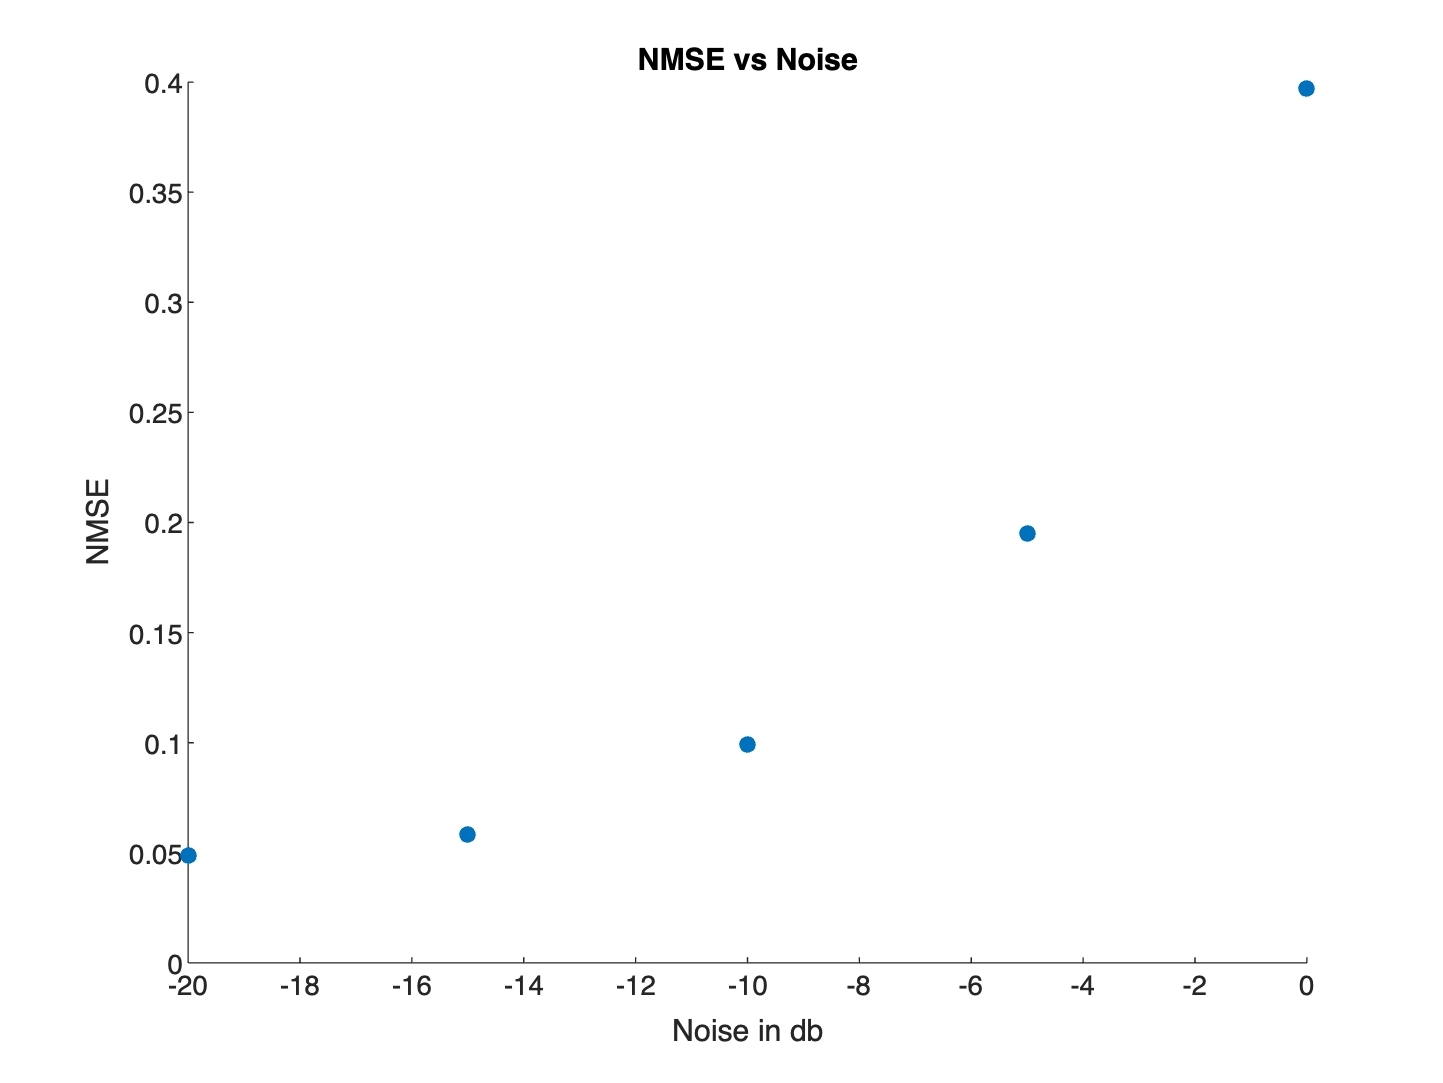

scatter(noise_var, NMSE, 'filled')
xlabel("Noise in db")
ylabel("NMSE")
title("NMSE vs Noise")